# Impedance matching considering electrical power

## from Strofer et al 2023: CCD of PTOs with WecOptTool


syms Z_i Z_fu Z_fi Z_vu Z_vi complex
syms F_e real

V_th = Z_vu / (Z_i - Z_fu) * F_e;
Z_th = Z_vi + (Z_fi * Z_vu) / (Z_i - Z_fu);
Z_abcd = [- Z_fi \ Z_fu, inv(Z_fi);
          Z_vu - Z_vi / Z_fi * Z_fu, Z_vi \ Z_fi];

IV_opt = [-1; conj(Z_th)] * V_th / (2 * real(Z_th));
UF_opt = Z_abcd \ IV_opt;
Zp_opt = ([0 1] * UF_opt) / ([1 0] * UF_opt)

simplify(Zp_opt)


## Retry

clear all
syms Z_d Z_w Z_i complex
syms K_t N_d F_e real positive

Z_fu = -N_d^2 * Z_d;
Z_fi = -sqrt(3/2)*K_t * N_d;
Z_vu = -sqrt(3/2)*K_t * N_d;
Z_vi = Z_w;

V_th = Z_vu / (Z_i - Z_fu) * F_e;
Z_th = Z_vi + (Z_fi * Z_vu) / (Z_i - Z_fu);
Z_abcd = [- Z_fi \ Z_fu, inv(Z_fi);
          Z_vu - Z_vi / Z_fi * Z_fu, Z_vi \ Z_fi];

IV_opt = [-1; conj(Z_th)] * V_th / (2 * real(Z_th));
UF_opt = Z_abcd \ IV_opt;
Zp_opt = ([0 1] * UF_opt) / ([1 0] * UF_opt)

simplify(Zp_opt)

## MASK basin workshop slides p153 - conversion efficiency

syms Z_L complex
Z_11 = Z_fu; Z_12 = Z_fi;
Z_21 = Z_vu; Z_22 = Z_vi;
fraction = Z_21 / ( (Z_11 + Z_i)*(Z_22 + Z_L) - Z_12*Z_21)
eta = 4 * real(Z_i) * real(Z_L) * abs(fraction)^2;

% sensitivity
can_change = [N_d, Z_d, K_t, Z_L];
J = gradient(eta,can_change)
assume(real(Z_i),'positive')
assume(real(Z_L),'positive')
conds = simplify(J==0)
conds134 = simplify(conds(1) & conds(3) & conds(4),100)
allConds = simplify(conds134 & conds(2), 100)


## Phase of different variables, as in MASK workshop slide 77

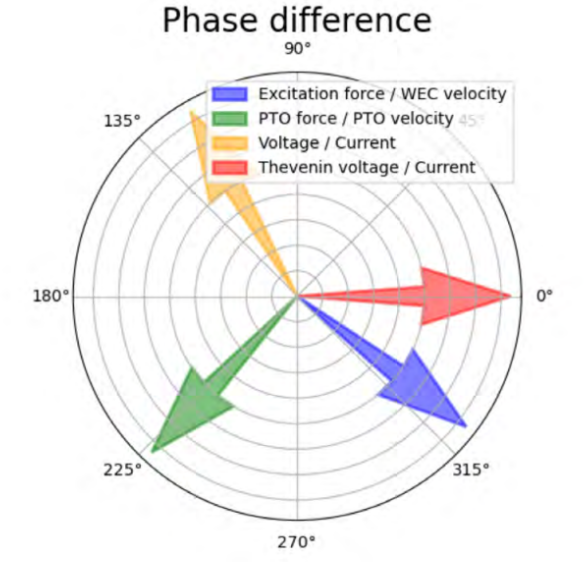

clear all
syms w m B_h B_pto N_d K_h K_t B_w L_w real positive
syms K_pto B_g K_g real
s = 1i * w;
B_eff = B_h + N_d^2 * B_pto;
K_eff = K_h + N_d^2 * K_pto;
Z_w = B_w + s * L_w;
K_m = sym(sqrt(3/2)) * K_t * N_d;
X_over_F = 1/(m*s^2 + B_eff*s + K_eff)
Vbemf_over_X = s * K_m;
Vw_over_Fgen = Z_w / K_m;
% never ended up computing phase and making the arrows but the var definitions are used in the
% cell below

## Max electrical power based on p64 of notebook

% this assumes Lw = 0
syms zeta_u w_n_u real positive
X_over_F = 1/m * 1/(s^2 + 2*zeta_u*w_n_u * s + w_n_u^2);

P_Fh2 = (X_over_F / (1/ (B_g * s + K_g) + X_over_F))^2 * (B_w/K_m^2 - s/(B_g*s + K_g));
eqn = diff(P_Fh2, K_g) == 0;
eqn2 = diff(P_Fh2, B_g) == 0;
sol = solve([eqn,eqn2],[K_g,B_g]);
Kg_opt = simplify(sol.K_g);
Bg_opt = simplify(sol.B_g);

syms w_star_u real positive
Kg_opt = simplify(subs(Kg_opt, w_n_u, w / w_star_u))
Bg_opt = simplify(subs(Bg_opt, w_n_u, w / w_star_u))
% this matches biconjugate matching from slides, see notebook p67-69

% power for saturated-optimal control for any given wec + pto
syms m_sat real positive % multiplier compared to optimal
P_Fh2mw = P_Fh2 * w * m;
P_Fh2mw_opt = subs(P_Fh2mw,{B_g,K_g},m_sat*{Bg_opt,Kg_opt});
P_Fh2mw_opt = simplify(subs(P_Fh2mw_opt, w_n_u, w / w_star_u));

% define nondimensional resistance R* = 2 * m * w * Bw / (3 * Kt^2 * Nd^2) to condense Bw, Kt, Nd, m, w into 1 param
syms R real positive
P_Fh2mw_opt = simplify(subs(P_Fh2mw_opt, B_w, 3/2 * R * K_t^2 * N_d^2 / (m * w)))
P_Fh2wm_opt_avg = simplify(real(P_Fh2mw_opt))

% this nondimensional power is just a fcn of c, m_sat, w_star_u, and zeta_u
R_vec = [0, 0.1, 1];
m_vec = [0.5, 1];
figure
for i = 1:length(R_vec)
    for j = 1:length(m_vec)
        R_val = R_vec(i);
        m_val = m_vec(j);
        subplot(length(m_vec), length(R_vec), i+length(R_vec)*(j-1))
        fcn = subs(P_Fh2wm_opt_avg, {R,m_sat}, {R_val,m_val});
        fcontour(fcn, [0,2,0,0.5], 'fill',true, ...
            'LevelList',[-4,-3,-2,-1,-0.75,-0.5,-0.25,-0.1,0])
        title(['R^* = ',num2str(R_val),', m_{sat} = ',num2str(m_val)])
        xlabel('\omega_u^*')
        ylabel('\zeta_u')
        colorbar
        grid on
        set(gca,'layer','top'); % make gridlines visible
        caxis([-4 0])
    end
end
% Conclusion: assuming negative power is generation, the trend makes sense
% that w_star_u = 1 is optimal, and that higher resistance (c) gives less
% power. I don't understand why zeta_u = 0 (undamped) appears optimal.

Kg_opt_noR = subs(Kg_opt,B_w,0)
Bg_opt_noR = subs(Bg_opt,B_w,0)

## Compute m_sat for generic off-matched impedance

% Using page 70-71 in notebook
clear all
syms a b real % a = real(Zth), b = imag(Zth)
syms m_sat real positive

% flow limited (current)
i_sat = 2*a / sqrt( (1+m_sat)^2*a^2 + (1-m_sat)^2*b^2 )
m_sat_flow = solve(i_sat,m_sat)
% idk why this can't solve, did it by hand on p75 and result is below
syms isat
sqroot = sqrt( ((a^2-b^2)/(a^2+b^2))^2 - 1 + 4*a^2/(isat^2 * (a^2+b^2)) )
m_sat_flow_plus = (b^2-a^2)/(b^2+a^2) + sqroot
m_sat_flow_minus = (b^2-a^2)/(b^2+a^2) - sqroot

% effort limited (voltage)
v_sat = 2*a/sqrt(a^2+b^2) * m_sat * sqrt(((1+m_sat)*a^2 - (1-m_sat)*b^2)^2 + (2*a*b*m_sat)^2) / ((1+m_sat)^2*a^2 + (1-m_sat)^2*b^2)
m_sat_effort = solve(v_sat,m_sat)

% try again:
syms vsat real positive
eqn = (a^2+b^2)*vsat^2/(4*a) == m_sat^2 * ( (a^2*(1+m_sat) - b^2*(1-m_sat))^2 + (2*a*b*m_sat)^2 ) / ((1+m_sat)^2*a^2 + (1-m_sat)^2*b^2)^2;
m_sat_effort = solve(eqn,m_sat,'ReturnConditions',true)

m_sat_effort = m_sat_effort.conditions

% plug in numbers for a, b, isat, vsat
i_vec = [0.5, 0.75, 0.9];
v_vec = [0.5, 0.75, 1];
figure
for i = 1:length(i_vec)
    i_val = i_vec(i);
    subplot(1, length(i_vec), i)
    fcn = subs(m_sat_flow_minus, isat, i_val);
    fcontour(fcn, [0,1], 'fill',true)
    title(['i_{sat} = ',num2str(i_val)])
    xlabel('a')
    ylabel('b')
    colorbar
    grid on
    set(gca,'layer','top'); % make gridlines visible
    %caxis([0 1])
end
sgtitle('m_{sat} for flow limiting')
figure
for i = 1:length(v_vec)
    v_val = v_vec(i);
    subplot(1, length(v_vec), i)
    fcn = subs(m_sat_effort, isat, v_val);
    fcontour(fcn, [0,1], 'fill',true)
    title(['v_{sat} = ',num2str(v_val)])
    xlabel('a')
    ylabel('b')
    colorbar
    grid on
    set(gca,'layer','top'); % make gridlines visible
    %caxis([-4 0])
end
sgtitle('m_{sat} for effort limiting')

## Power equation verification

% eqn on page 80 of notebook
clear all
syms m_sat Z_th
P_Vth2 = 1/2 * real(m_sat * Z_th') / ( abs(Z_th)^2 + abs(m_sat * Z_th')^2 + 2*real(m_sat * Z_th'^2) );
P_opt_Vth2 = 1/(8 * real(Z_th));

gamma = (m_sat - 1)/(m_sat+1);

P_ratio = P_Vth2 / P_opt_Vth2;
hopeTrue = P_ratio == 1 - abs(gamma)^2
simplify(hopeTrue,500)

figure
ZMIN = 0; ZMAX = 1; MMIN = 0; MMAX = 1;
fcontour(P_Vth2,[ZMIN ZMAX MMIN MMAX])
xlabel('Re(Z_{th})')
ylabel('Re(m_{sat})')
title('P / V_{th}^2')
colorbar

figure
ZMIN = 0; ZMAX = 1; MMIN = 0; MMAX = 1;
fcontour(P_ratio,[ZMIN ZMAX MMIN MMAX])
xlabel('Re(Z_{th})')
ylabel('Re(m_{sat})')
title('P ratio')
colorbar

figure
fplot(subs(P_ratio,Z_th,0.5),[MMIN MMAX])
xlabel('Re(m_{sat})')
title('P ratio for Z_{th}=0.5')

figure
fplot(subs(P_ratio,Z_th,1+0.5*1i),[MMIN MMAX])
xlabel('Re(m_{sat})')
title('P ratio for Z_{th}=1+0.5 i')

figure
fplot(1 - abs(gamma)^2,[MMIN MMAX])
xlabel('Re(m_{sat})')
title('1-|\gamma|^2')

## Power equation on Smith Plot

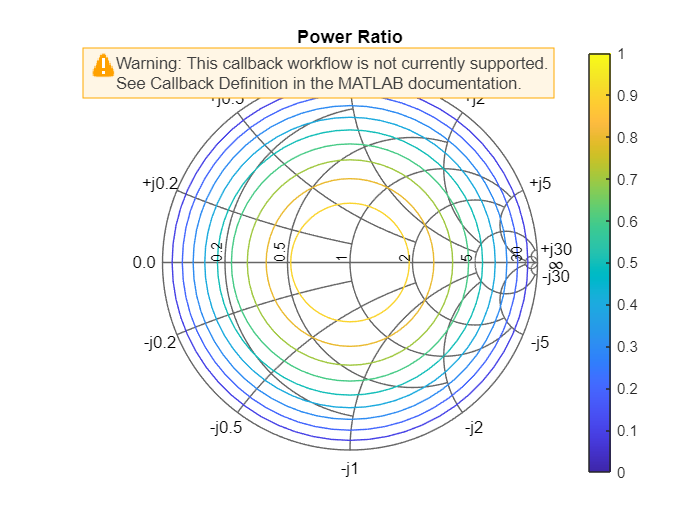


mag_delta = 0.01;
phase_delta = pi/30;

[MagGamma,PhaseGamma] = meshgrid(0:mag_delta:1, 0:phase_delta:2*pi);
ReGamma = MagGamma .* cos(PhaseGamma);
ImGamma = MagGamma .* sin(PhaseGamma);
gamma = ReGamma + 1i * ImGamma;
z = -(gamma + 1) ./ (gamma - 1);
m1 = real(z);
m2 = imag(z);

power_ratio = 1-MagGamma.^2;
mySmithPlot(ReGamma, ImGamma, power_ratio, 'Power Ratio')

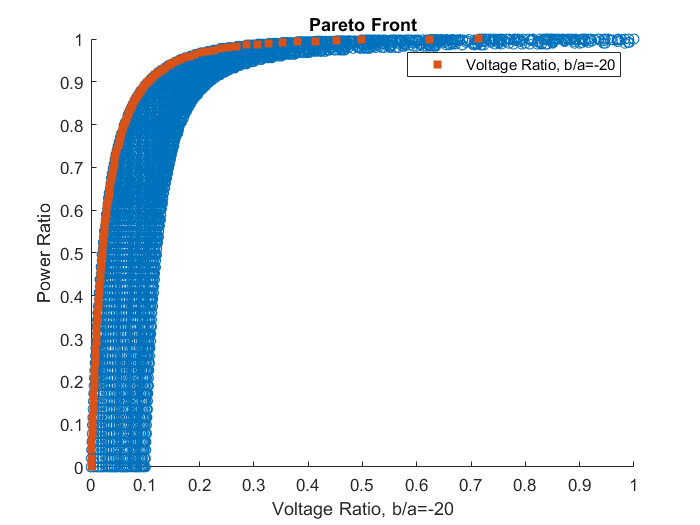

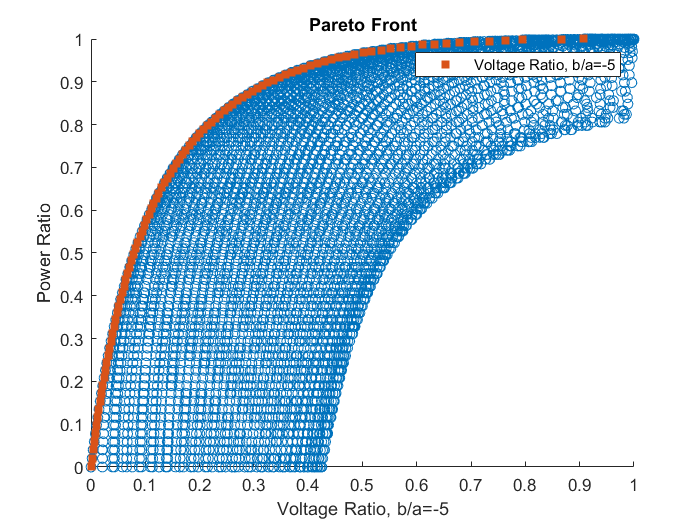

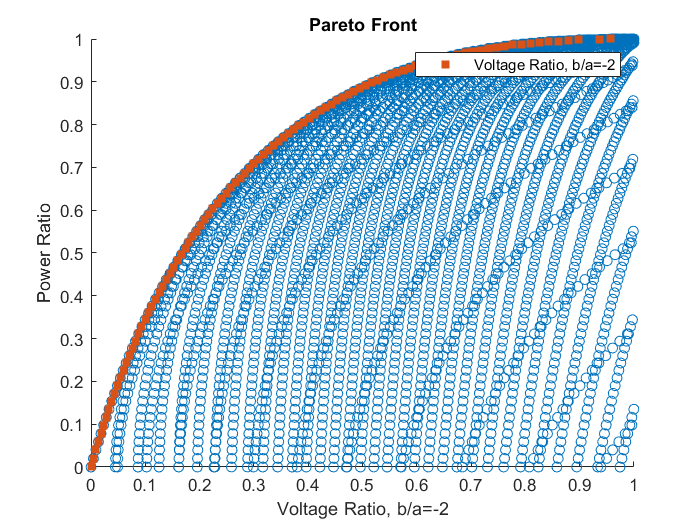

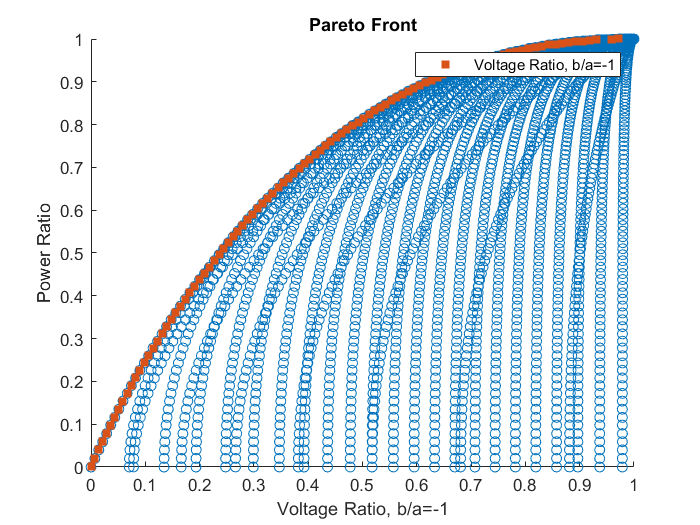

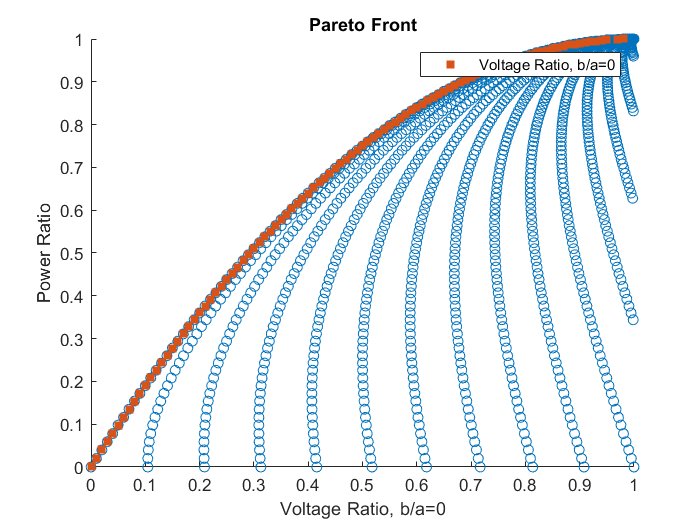

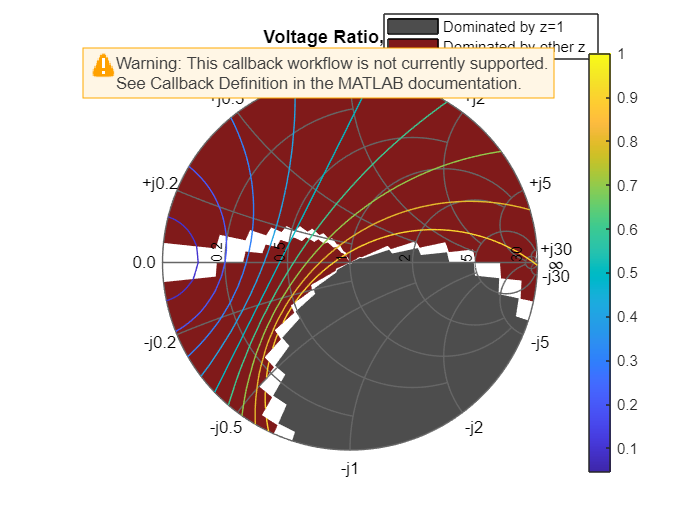

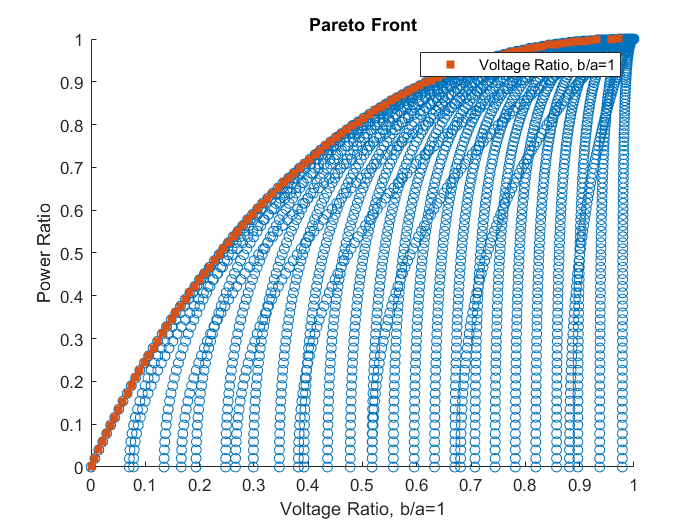

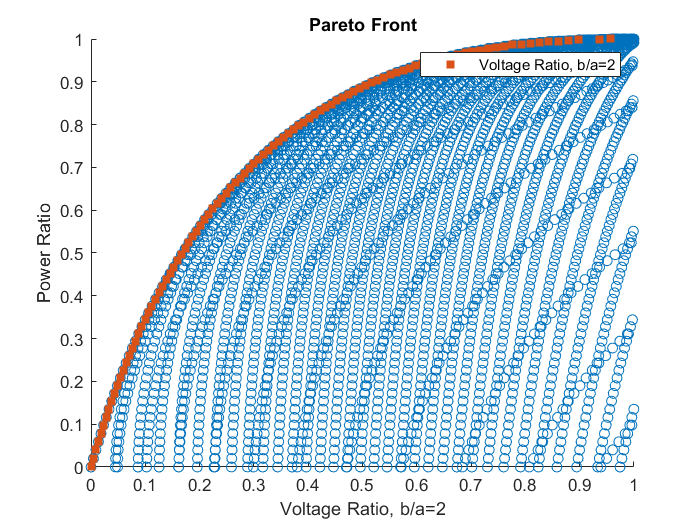


sq_coeff = m2.^2 + (1-m1).^2;
lin_coeff = 4*m2;
const_coeff = m2.^2 + (1+m1).^2;
b_over_a = [-20, -5, -2, -1, 0, 1, 2, 5, 20];

% for b_a = b_over_a
%     sqrt_term = b_a^2 * sq_coeff + b_a * lin_coeff + const_coeff;
%     sqrt_term(sqrt_term<0) = 1e-16;
%     currentRatio = 2 ./ sqrt(sqrt_term);
%     mySmithPlot(ReGamma, ImGamma, currentRatio, ['Current Ratio, b/a=', num2str(b_a)])
% end

figure(2)
clf
hold on
legend

for b_a = b_over_a
    complex_term = z * (1 - b_a * 1i) ./ (1 + z + (1 - z)*b_a*1i);
    voltageRatio = 2/sqrt(1 + b_a^2) * abs(complex_term);
    [Z1_non_dom, Z2_non_dom] = mySmithPlot(ReGamma, ImGamma, voltageRatio, ['Voltage Ratio, b/a=', num2str(b_a)], power_ratio);
    if b_a >= 0 % only plot positive because pos and neg are the same
        figure(2)
        plot(Z1_non_dom,Z2_non_dom,'DisplayName',['|b/a|=',num2str(b_a)])
    end
end

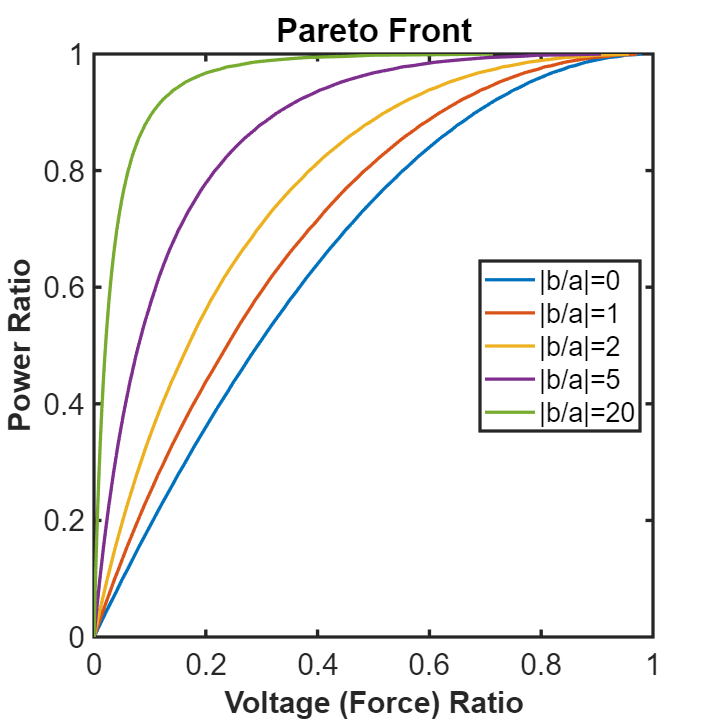


figure(2)
xlabel('Voltage (Force) Ratio')
ylabel('Power Ratio')
title('Pareto Front')
improvePlot

function [Z1_nondom_sorted, Z2_nondom_sorted] = mySmithPlot(X,Y,Z,titleString,Z_pareto_compare)
    figure('Color',[1 1 1])
    smithplot('TitleTop',titleString);
    hold on
    levs = 0:0.1:1;
    Z_capped = Z;
    Z_capped(Z>1) = NaN;
    contour(X, Y, Z_capped, levs, 'HandleVisibility','off');

    grey = [.3 .3 .3];
    red = [.5 .1 .1];

    % dark grey shading where Z>1
    if max(Z,[],'all') > 1
        Z_caps = Z;
        Z_caps(Z<=1) = NaN;
        contourf(X, Y, Z_caps,0,'FaceColor',grey,'HandleVisibility','off')
        patch(NaN,NaN,grey,'DisplayName','Dominated by z=1') % dummy patch for legend
    end

    cb = colorbar;
    scale = 0.8; % smaller colorbar
    cb.Position = [cb.Position(1), cb.Position(2)+0.1, ...
        cb.Position(3)*scale cb.Position(4)*scale];

    if nargin>4
        Z_pareto_compare = round(Z_pareto_compare,3);
        p = [-Z_capped(:), Z_pareto_compare(:)]; % assumes max Z is better
        [~, non_dom_idxs] = paretoFront(p);
        
        % red shading where dominated
        Z_dom = Z_capped;
        Z_dom(non_dom_idxs) = NaN;
        contourf(X,Y,Z_dom,0,'FaceColor',red,'HandleVisibility','off')
        patch(NaN,NaN,red, 'DisplayName','Dominated by other z') % dummy patches for the sake of legend
        legend
        
        % pareto front with dom and non dom points
        figure
        scatter(Z_capped(:),Z_pareto_compare(:),'HandleVisibility','off')
        hold on
        Z1_nondom = Z_capped(non_dom_idxs);
        Z2_nondom = Z_pareto_compare(non_dom_idxs);
        scatter(Z1_nondom, Z2_nondom,'s','Filled','DisplayName',titleString)
        xlabel(titleString)
        ylabel('Power Ratio')
        title('Pareto Front')
        legend

        [Z1_nondom_sorted,sort_idxs] = sort(Z1_nondom);
        Z2_nondom_sorted = Z2_nondom(sort_idxs);
    end


end
